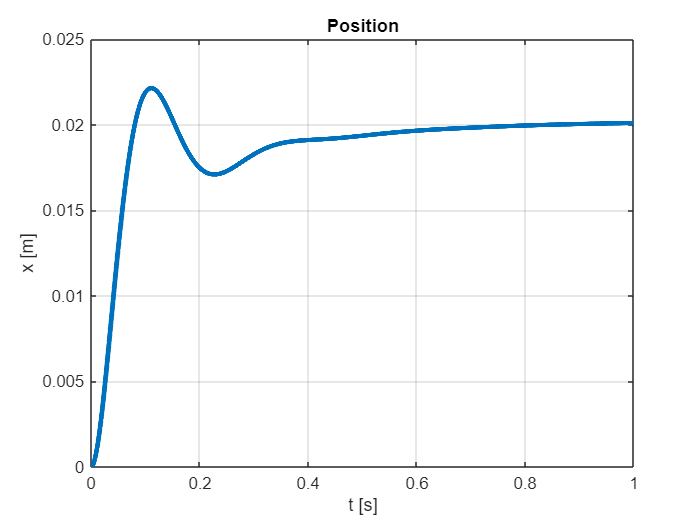

run("cart/cart_parameters.m")
% Initial state
X0 = [0; 0; 5*pi/180; 0];

% SIMULINK
% Regulator (Inner Loop)
Kp_t = 20;
Td_t = 1;
Ti_t = 0;

% Regulator (Outer Loop)
Kp_v = 0.2;
Td_v = 0;
Ti_v = 0;

Tsim = 1;
%  (vref = 0), keep stable position
t = 0:0.01:1;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("cart/cart_robot_sim.slx");

x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
theta_v = out.simout.signals.values(:,3);
dtheta_v = out.simout.signals.values(:,4);
t_v = out.tout;

% x
figure;
plot(t_v, x_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('x [m]');
title('Position');
grid on;

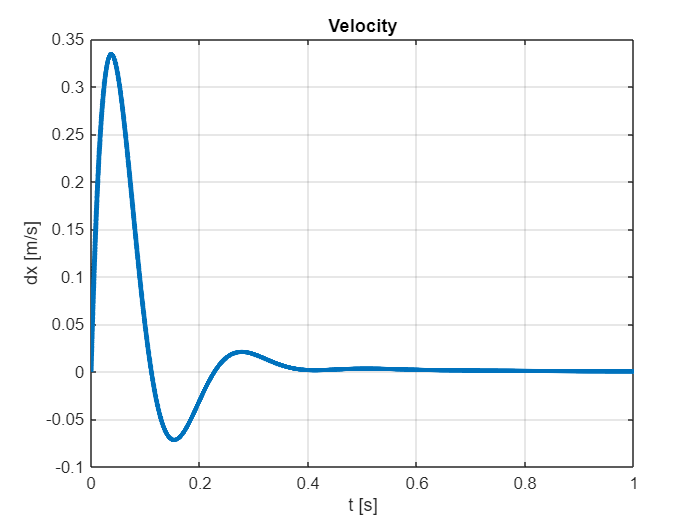


% dx
figure;
plot(t_v, dx_v, "LineWidth", 3);
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
grid on;

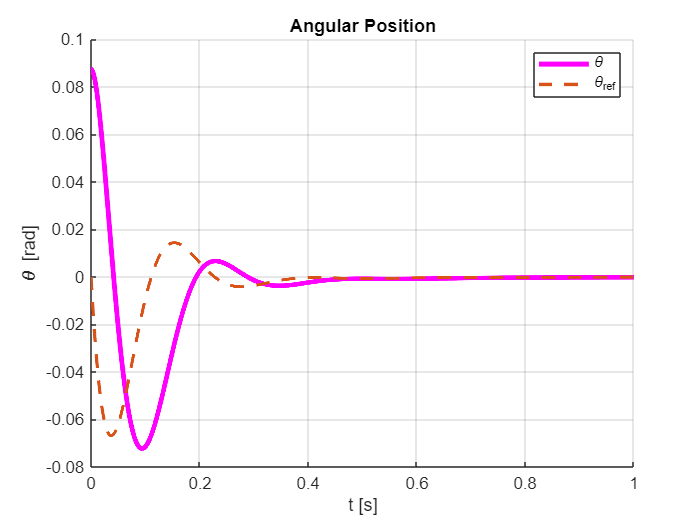


% theta
figure;
hold on;
plot(t_v, theta_v, "LineWidth", 3,"Color","magenta","DisplayName","\theta");
% Extract theta_ref
theta_ref = out.simout1.signals.values;
plot(t_v, theta_ref, 'LineWidth', 2,"DisplayName","\theta_{ref}","LineStyle","--");
xlabel('t [s]');
ylabel('\theta [rad]');
title('Angular Position');
legend('show');
grid on;

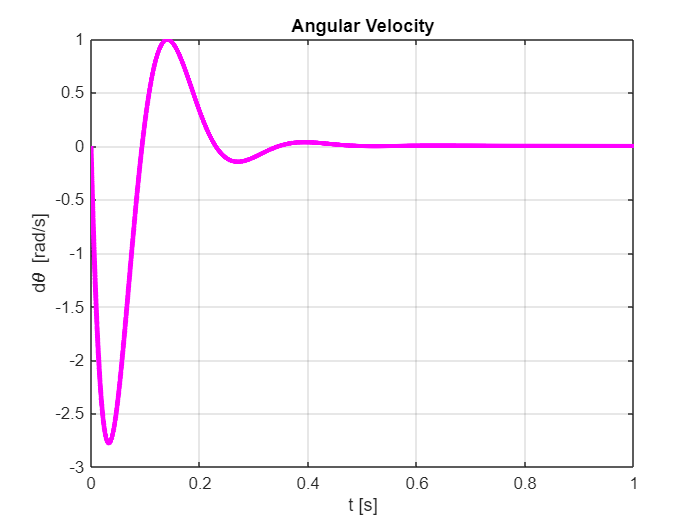


% dtheta
figure;
plot(t_v, dtheta_v, "LineWidth", 3,"Color","magenta");
xlabel('t [s]');
ylabel('d\theta [rad/s]');
title('Angular Velocity');
grid on;

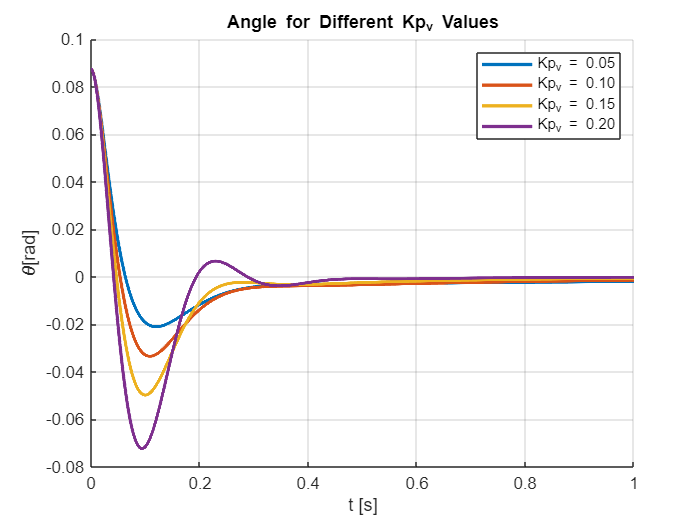






figure;
hold on;
grid on;
Kp_v_values = [0.05 0.1 0.15 0.2];   % values to compare

for i = 1:length(Kp_v_values)

    % Update current Kp
    Kp_v = Kp_v_values(i);

    % Run simulation
    out = sim("cart/cart_robot_sim.slx");

    % Extract position
    x_v = out.simout.signals.values(:,3);
    t_v = out.tout;

    % Plot
    plot(t_v, x_v, 'LineWidth', 2, ...
        'DisplayName', sprintf('Kp_v = %.2f', Kp_v));
end

xlabel('t [s]');
ylabel('\theta[rad]');
title('Angle for Different Kp_v Values');
legend('show');

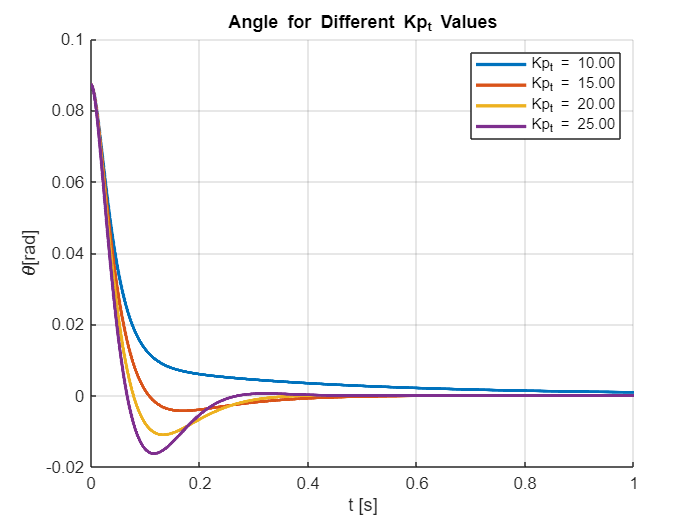

figure;
hold on;
grid on;
Kp_t_values = [10 15 20 25];   % values to compare
Kp_v = 0;

for i = 1:length(Kp_t_values)

    % Update current Kp
    Kp_t = Kp_t_values(i);

    % Run simulation
    out = sim("cart/cart_robot_sim.slx");

    % Extract position
    x_v = out.simout.signals.values(:,3);
    t_v = out.tout;

    % Plot
    plot(t_v, x_v, 'LineWidth', 2, ...
        'DisplayName', sprintf('Kp_t = %.2f', Kp_t));
end

xlabel('t [s]');
ylabel('\theta[rad]');
title('Angle for Different Kp_t Values');
legend('show');